# Horizontal line scan data

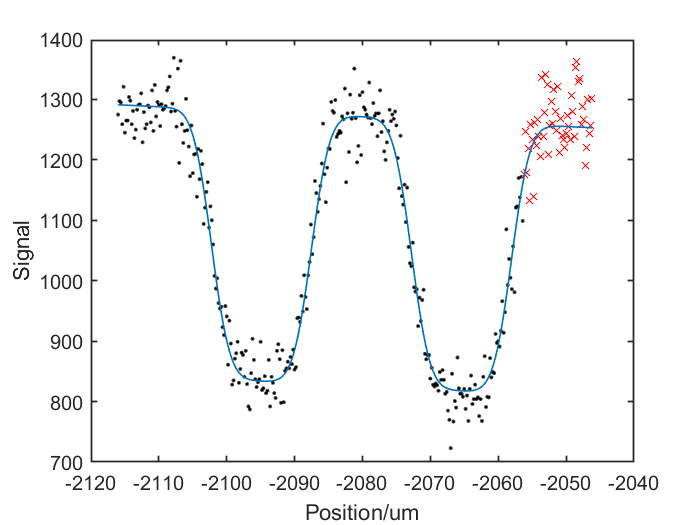

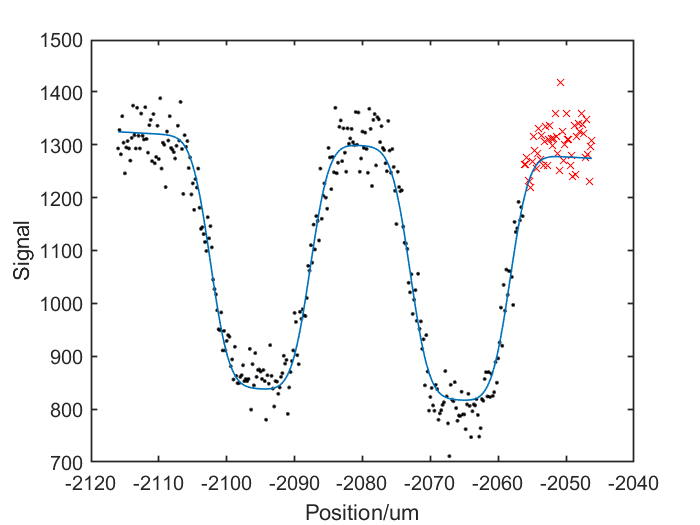

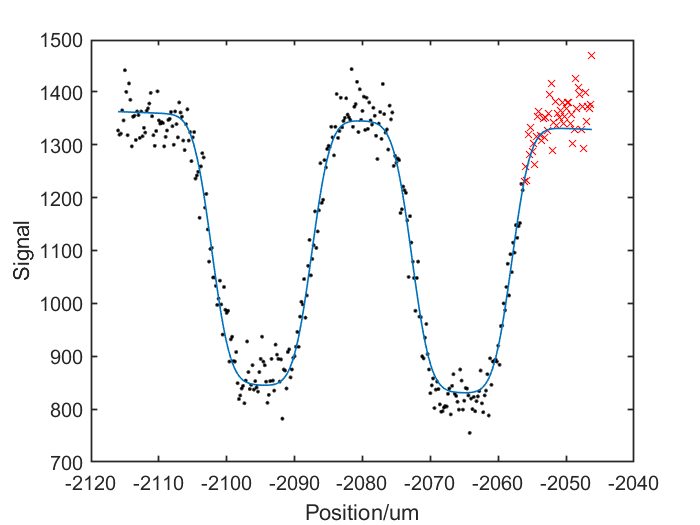

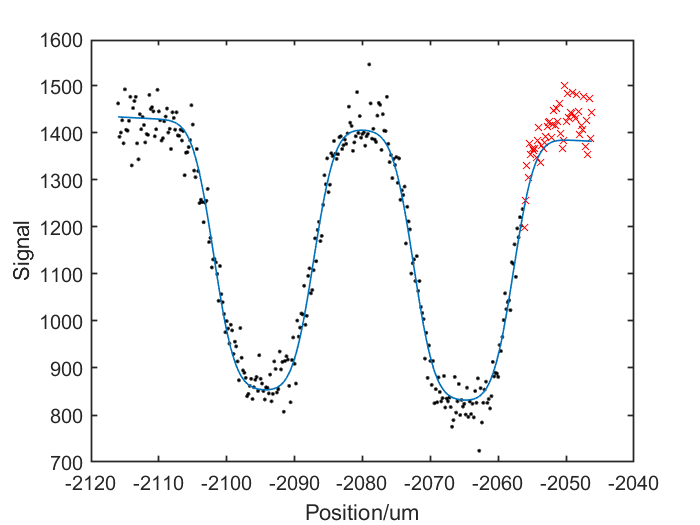

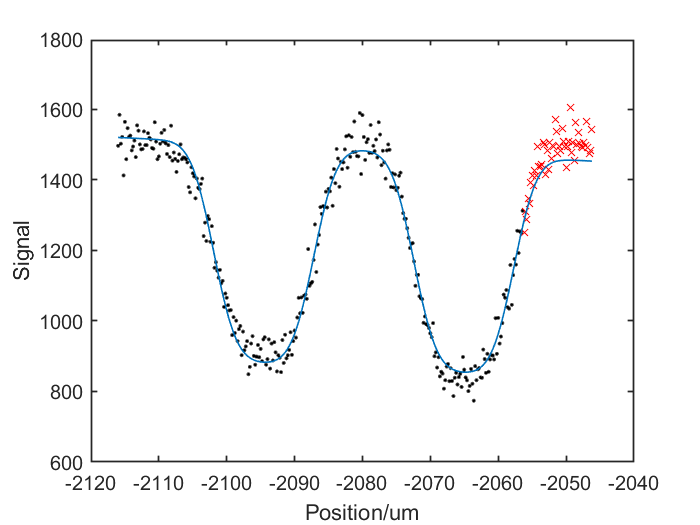

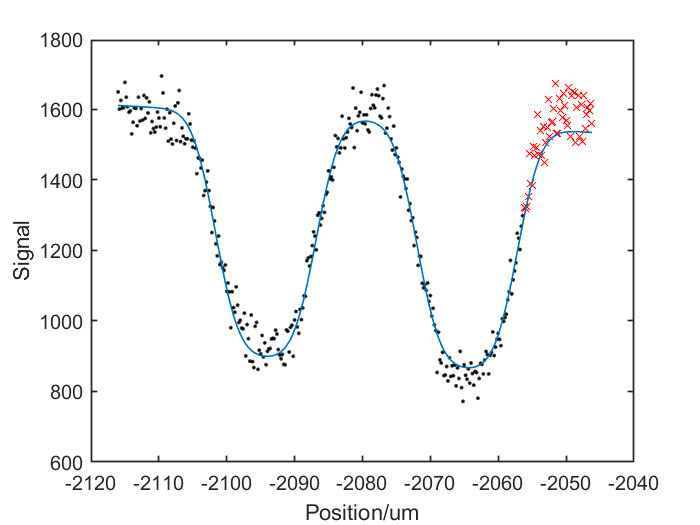

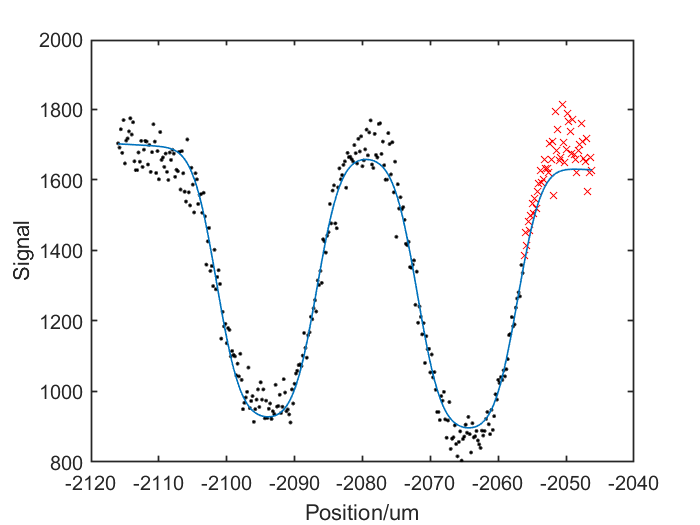

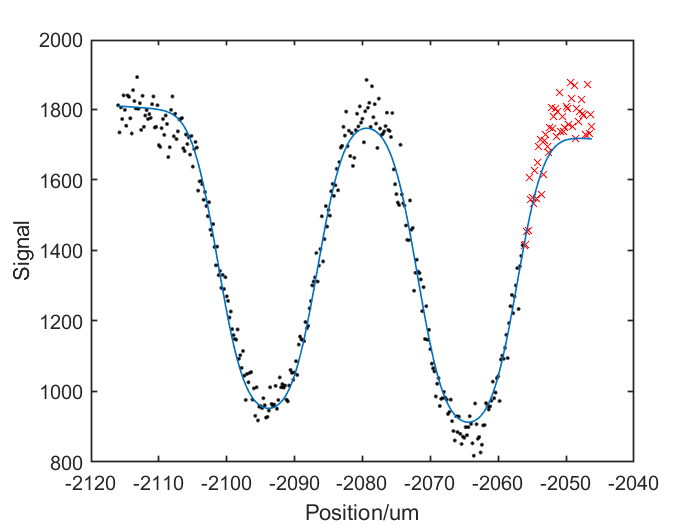

%Load in the data
data=read_LSN_data('Data\16-Feb-2021_002.lsn');

%Set the z positions of the scans
%Grab number of points and spacing of them
delta_z=data.step_size(2);
N_z=data.num_pixels(2);

%Generate the x positions of each data point
z=data.start(3):delta_z:data.start(3)+delta_z*(N_z-1);

%x positions
%Grab number of points and spacing of them
delta=data.step_size(1);
N=data.num_pixels(1);

%Generate the x positions of each data point
x=data.start(1):-delta:data.start(1)-delta*(N-1);
%figure;plot(x,data.image)
%figure;plot(data.image(:,1))

%Initialise memory
sigma_z=NaN*ones(1,N_z);
sigma_z_error=NaN*ones(1,N_z);
mu_z=NaN*ones(1,N_z);
mu_z_error=NaN*ones(1,N_z);
a_z=NaN*ones(1,N_z);
a_z_error=NaN*ones(1,N_z);
c_z=NaN*ones(1,N_z);
c_z_error=NaN*ones(1,N_z);


%Main loop over each dataset
for n=1:N_z
    
    
    %Choose where to crop the data off to only include the 15um slits
    slit_15_end=350;
    y_crop=data.image(1:slit_15_end,n);
    x_crop=x(1:slit_15_end);
    
    %Set point near the edge so there is no influence from the 10um slits
    %when the beam gets very large
    slit_15_mid=300;
    
    N_crop=length(y_crop);
    
    % Fit 4 error functions to the data to estimate the width and position
    [xData, yData] = prepareCurveData( x_crop, y_crop );
    
    % Set up fittype and options.
    ft = fittype( 'a*(normcdf(x,mu,sigma)-normcdf(x,mu+d,sigma)+normcdf(x,mu+2*d,sigma)-normcdf(x,mu+3*d,sigma))+m*(x-mu)+c', 'independent', 'x', 'dependent', 'y' );
    excludedPoints = excludedata( xData, yData, 'Indices', [slit_15_mid:N_crop ] );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    %opts.StartPoint = [-300 700 12 1 -1660 2];
    opts.StartPoint = [-1000 2000 12 1 -2100 2];
    opts.Upper = [Inf Inf Inf Inf 0 Inf];
    opts.Exclude = excludedPoints;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    %Plot the output
    figure;plot(x_crop(1:slit_15_mid-1),y_crop(1:slit_15_mid-1),'k.')
    hold on
    plot(x_crop(slit_15_mid:end),y_crop(slit_15_mid:end),'rx')
    plot(x_crop,fitresult(x_crop),'LineWidth',1,'Color',	[0, 0.4470, 0.7410])
    xlabel('Position/um')
    ylabel('Signal')
    
    set(gca,'FontSize',12,'LineWidth',1)
    
    %Save outputs
    error=confint(fitresult,0.6827);
    
    sigma_z(n)=fitresult.sigma;
    sigma_z_error(n)=diff(error(:,6))/2;
    
    mu_z(n)=fitresult.mu;
    mu_z_error(n)=diff(error(:,5))/2;
    
    a_z(n)=fitresult.a;
    
    c_z(n)=fitresult.c;
    
    
end

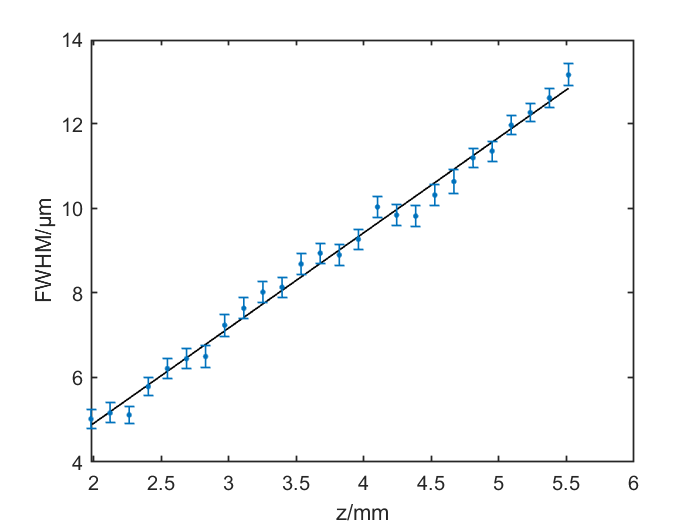


%Estimate of the true z position
z2=(4.5e3-z)*sqrt(2);

%Calculate the full width at half maximum
FWHM=sigma_z*2*sqrt(2*log(2));
FWHM_error=sigma_z_error*2*sqrt(2*log(2));


%Fit a straight line
[xData, yData] = prepareCurveData( z2, FWHM );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [19 20] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
%opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

lin_error=confint(fitresult,0.6827);


%Plot the FWHM
figure;plot(z2/1e3,fitresult(z2),'k','LineWidth',1)
hold on
errorbar(z2/1e3,FWHM,FWHM_error,'.','LineWidth',1,'MarkerSize',10,'Color',	[0, 0.4470, 0.7410])
%errorbar(z2(19:20)/1e3,FWHM(19:20),FWHM_error(19:20),'.','LineWidth',1,'MarkerSize',10,'Color',	[1, 0, 0])
ylabel(['FWHM/',char(181),'m'])
xlabel(['z/mm'])
%xlim([0 4])
%ylim([0 14])
set(gca,'FontSize',12,'LineWidth',1)


%Estimate angular source size
beta=fitresult.p1*sqrt(3)/(2*sqrt(2*log(2)));
beta_error=(diff(lin_error(:,1))/2)*sqrt(3)/(2*sqrt(2*log(2)));

%Estimate the size of the skimmer
r_skim_guess=beta*68.5e-3;
r_skim_guess_error=beta_error*68.5e-3;

d_skim_guess=r_skim_guess*2;
d_skim_guess_error=r_skim_guess_error*2;

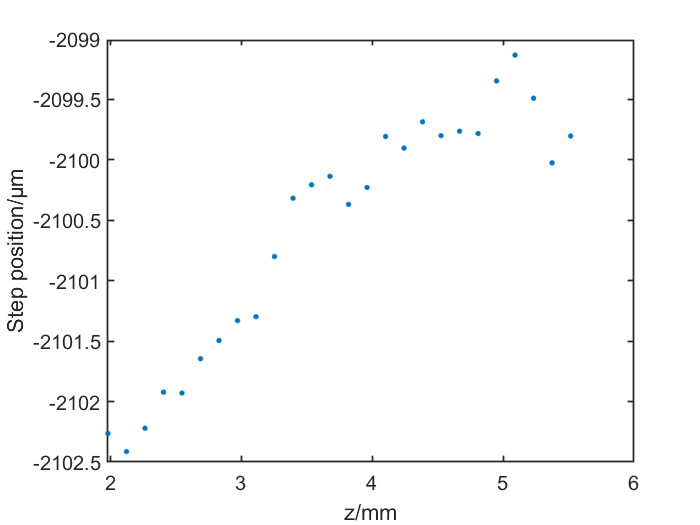


%Plot the positions of the edges
figure;plot(z2/1e3,mu_z,'.','LineWidth',1,'MarkerSize',10)
ylabel(['Step position/',char(181),'m'])
xlabel(['z/mm'])
%xlim([1.9 3.6])
set(gca,'FontSize',12,'LineWidth',1)

Still some drift of the edge, but it is only a few microns over a 1.5mm movement of the z stage.

Estimate of contribution from the pinhole itself

d=5;
fwhm_d=(d/(sqrt(3)))*sqrt(2*log(2))

fwhm_d = 3.3989

Would be too small to see in the graph yet.

## Combining the data sets

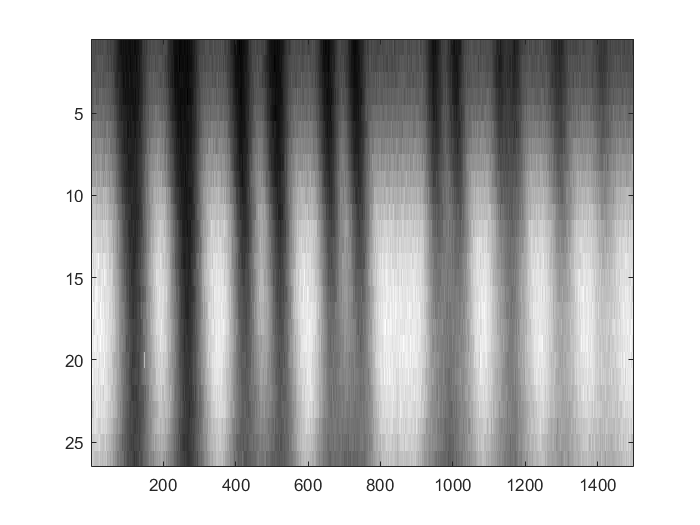

%Load in the second row of scans
data2=read_LSN_data('Data\17-Feb-2021_002.lsn');

combined_data=[data.image;data2.image];
N_comb=size(combined_data,1);
x_comb=data.start(1):-delta:data.start(1)-delta*(N_comb-1);

%figure;plot(combined_data(:,10))


%Remove spikes
[combined_data_clean,L_clip]=spike_im_removal(combined_data,4.2);

figure;imagesc(rot90(flip(combined_data_clean),3))
colormap gray

Split into slit sets

slit_15_inds=[1,350];
slit_10_inds=[351,580];
slit_8_inds=[581,850];
slit_6_inds=[851,1080];
slit_4_inds=[1081,1220];
slit_2_inds=[1221,1370];
slit_1_inds=[1371,1500];


## Checking allignment

Break up slits using the shifted co-ordinates instead of the index to stop drifts.

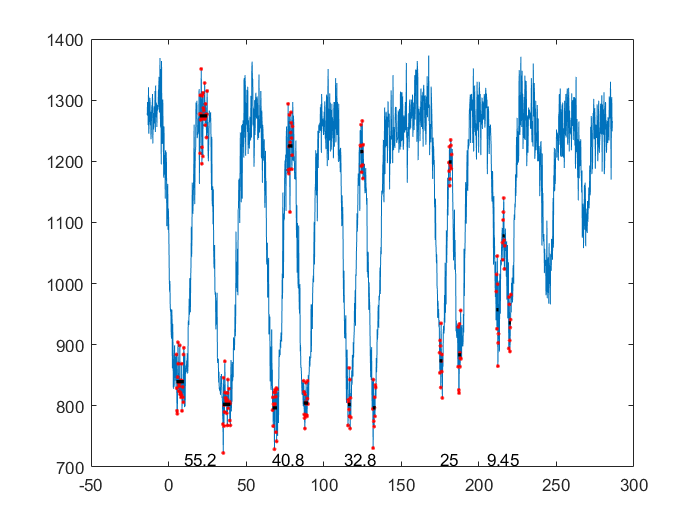

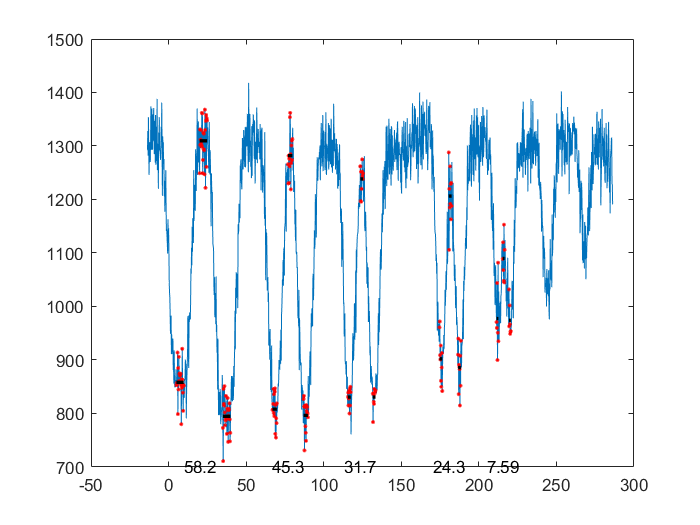

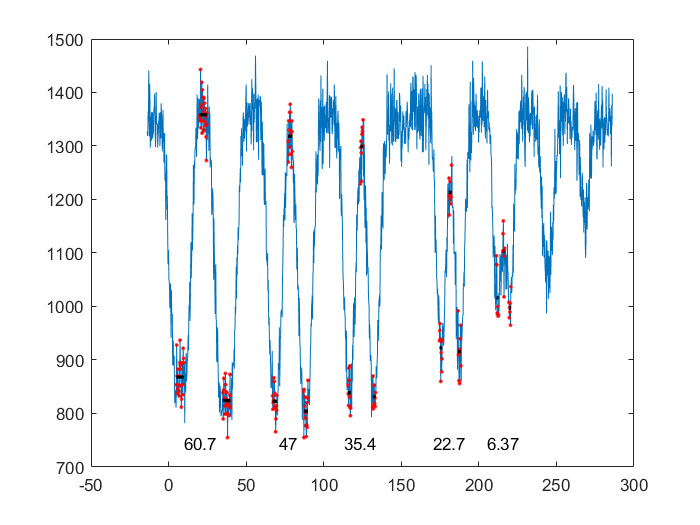

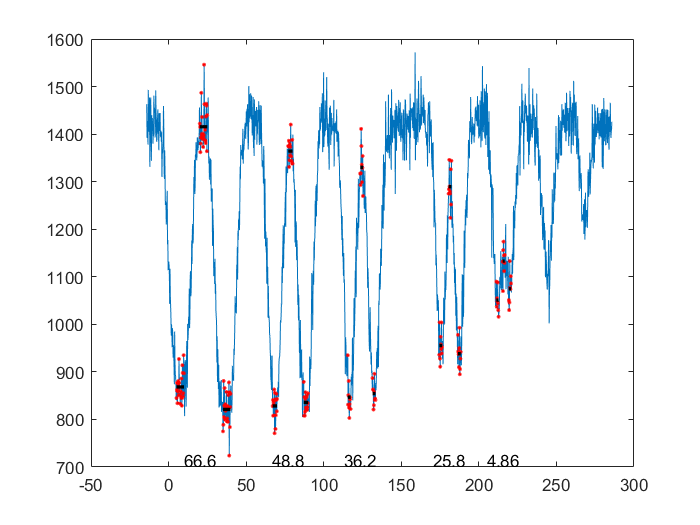

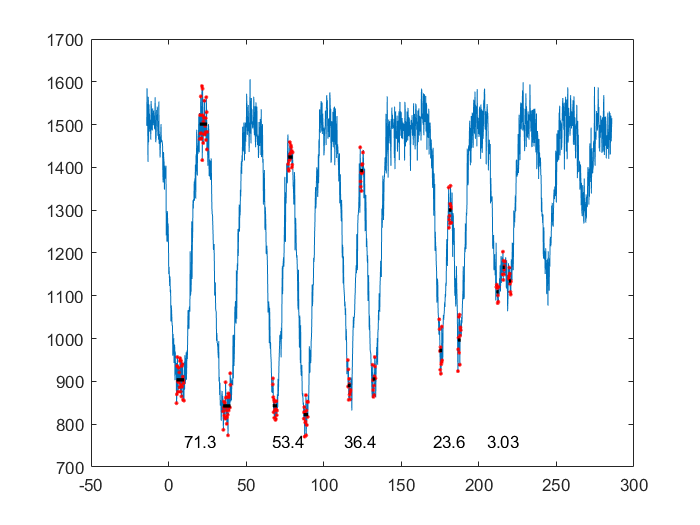

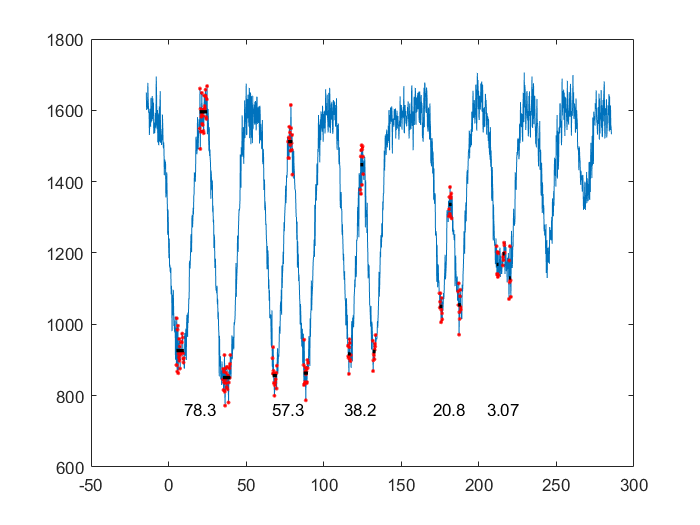

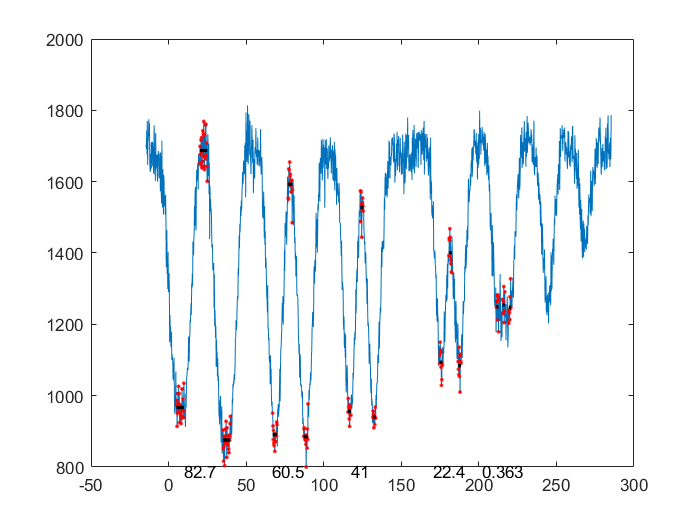

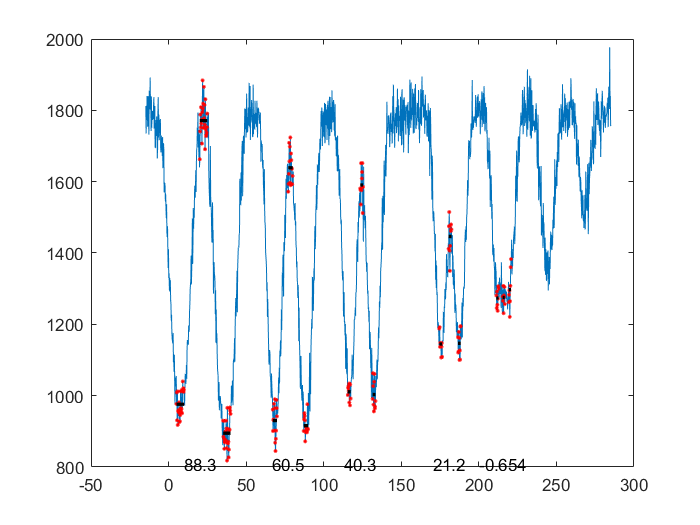

min_15_1=[5,10];
max_15=[20,25];
min_15_2=[35,40];

min_10_1=[67,70];
max_10=[77,80];
min_10_2=[87,90];

min_8_1=[115.5,117.5];
max_8=[123.5,125.5];
min_8_2=[131.5,133.5];

min_6_1=[174.5,176.5];
max_6=[180.5,182.5];
min_6_2=[186.5,188.5];

min_4_1=[211.25,212.75];
max_4=[215.25,216.75];
min_4_2=[219.25,220.75];

%Now find the values at those positions

min_15_1_inds_lim=NaN*zeros(2,N_z);
min_15_2_inds_lim=NaN*zeros(2,N_z);
max_15_inds_lim=NaN*zeros(2,N_z);

I_min_15_1=NaN*zeros(1,N_z);
I_min_15_2=NaN*zeros(1,N_z);
I_max_15=NaN*zeros(1,N_z);

min_10_1_inds_lim=NaN*zeros(2,N_z);
min_10_2_inds_lim=NaN*zeros(2,N_z);
max_10_inds_lim=NaN*zeros(2,N_z);

I_min_10_1=NaN*zeros(1,N_z);
I_min_10_2=NaN*zeros(1,N_z);
I_max_10=NaN*zeros(1,N_z);

min_8_1_inds_lim=NaN*zeros(2,N_z);
min_8_2_inds_lim=NaN*zeros(2,N_z);
max_8_inds_lim=NaN*zeros(2,N_z);

I_min_8_1=NaN*zeros(1,N_z);
I_min_8_2=NaN*zeros(1,N_z);
I_max_8=NaN*zeros(1,N_z);

min_6_1_inds_lim=NaN*zeros(2,N_z);
min_6_2_inds_lim=NaN*zeros(2,N_z);
max_6_inds_lim=NaN*zeros(2,N_z);

I_min_6_1=NaN*zeros(1,N_z);
I_min_6_2=NaN*zeros(1,N_z);
I_max_6=NaN*zeros(1,N_z);

min_4_1_inds_lim=NaN*zeros(2,N_z);
min_4_2_inds_lim=NaN*zeros(2,N_z);
max_4_inds_lim=NaN*zeros(2,N_z);

I_min_4_1=NaN*zeros(1,N_z);
I_min_4_2=NaN*zeros(1,N_z);
I_max_4=NaN*zeros(1,N_z);

% Loop over each z position
for n=1:N_z
    %15 um
    min_15_1_inds=find(x_comb-mu_z(n)>=min_15_1(1) & x_comb-mu_z(n)<min_15_1(2));
    min_15_2_inds=find(x_comb-mu_z(n)>=min_15_2(1) & x_comb-mu_z(n)<min_15_2(2));
    max_15_inds=find(x_comb-mu_z(n)>=max_15(1) & x_comb-mu_z(n)<max_15(2));
    
    min_15_1_inds_lim(:,n)=[min_15_1_inds(1),min_15_1_inds(end)];
    min_15_2_inds_lim(:,n)=[min_15_2_inds(1),min_15_2_inds(end)];
    max_15_inds_lim(:,n)=[max_15_inds(1),max_15_inds(end)];
    
    
    I_min_15_1(n)=mean(combined_data(min_15_1_inds,n));
    I_min_15_2(n)=mean(combined_data(min_15_2_inds,n));
    I_max_15(n)=mean(combined_data(max_15_inds,n));
    
    
    
    %10 um
    min_10_1_inds=find(x_comb-mu_z(n)>=min_10_1(1) & x_comb-mu_z(n)<min_10_1(2));
    min_10_2_inds=find(x_comb-mu_z(n)>=min_10_2(1) & x_comb-mu_z(n)<min_10_2(2));
    max_10_inds=find(x_comb-mu_z(n)>=max_10(1) & x_comb-mu_z(n)<max_10(2));
    
    min_10_1_inds_lim(:,n)=[min_10_1_inds(1),min_10_1_inds(end)];
    min_10_2_inds_lim(:,n)=[min_10_2_inds(1),min_10_2_inds(end)];
    max_10_inds_lim(:,n)=[max_10_inds(1),max_10_inds(end)];
    
    
    I_min_10_1(n)=mean(combined_data(min_10_1_inds,n));
    I_min_10_2(n)=mean(combined_data(min_10_2_inds,n));
    I_max_10(n)=mean(combined_data(max_10_inds,n));
    
    
    %8 um
    min_8_1_inds=find(x_comb-mu_z(n)>=min_8_1(1) & x_comb-mu_z(n)<min_8_1(2));
    min_8_2_inds=find(x_comb-mu_z(n)>=min_8_2(1) & x_comb-mu_z(n)<min_8_2(2));
    max_8_inds=find(x_comb-mu_z(n)>=max_8(1) & x_comb-mu_z(n)<max_8(2));
    
    min_8_1_inds_lim(:,n)=[min_8_1_inds(1),min_8_1_inds(end)];
    min_8_2_inds_lim(:,n)=[min_8_2_inds(1),min_8_2_inds(end)];
    max_8_inds_lim(:,n)=[max_8_inds(1),max_8_inds(end)];
    
    
    I_min_8_1(n)=mean(combined_data(min_8_1_inds,n));
    I_min_8_2(n)=mean(combined_data(min_8_2_inds,n));
    I_max_8(n)=mean(combined_data(max_8_inds,n));
    
    %6 um
    min_6_1_inds=find(x_comb-mu_z(n)>=min_6_1(1) & x_comb-mu_z(n)<min_6_1(2));
    min_6_2_inds=find(x_comb-mu_z(n)>=min_6_2(1) & x_comb-mu_z(n)<min_6_2(2));
    max_6_inds=find(x_comb-mu_z(n)>=max_6(1) & x_comb-mu_z(n)<max_6(2));
    
    min_6_1_inds_lim(:,n)=[min_6_1_inds(1),min_6_1_inds(end)];
    min_6_2_inds_lim(:,n)=[min_6_2_inds(1),min_6_2_inds(end)];
    max_6_inds_lim(:,n)=[max_6_inds(1),max_6_inds(end)];
    
    
    I_min_6_1(n)=mean(combined_data(min_6_1_inds,n));
    I_min_6_2(n)=mean(combined_data(min_6_2_inds,n));
    I_max_6(n)=mean(combined_data(max_6_inds,n));
    
    %4 um
    min_4_1_inds=find(x_comb-mu_z(n)>=min_4_1(1) & x_comb-mu_z(n)<min_4_1(2));
    min_4_2_inds=find(x_comb-mu_z(n)>=min_4_2(1) & x_comb-mu_z(n)<min_4_2(2));
    max_4_inds=find(x_comb-mu_z(n)>=max_4(1) & x_comb-mu_z(n)<max_4(2));
    
    min_4_1_inds_lim(:,n)=[min_4_1_inds(1),min_4_1_inds(end)];
    min_4_2_inds_lim(:,n)=[min_4_2_inds(1),min_4_2_inds(end)];
    max_4_inds_lim(:,n)=[max_4_inds(1),max_4_inds(end)];
    
    
    I_min_4_1(n)=mean(combined_data(min_4_1_inds,n));
    I_min_4_2(n)=mean(combined_data(min_4_2_inds,n));
    I_max_4(n)=mean(combined_data(max_4_inds,n));
end
%15um
I_min_15=mean([I_min_15_1;I_min_15_2]);
D_15=I_max_15-I_min_15;
sigma_15=sqrt(mean([I_min_15;I_max_15]));
N_min1_15=diff(min_15_1_inds_lim)+1;
N_min2_15=diff(min_15_2_inds_lim)+1;
N_max_15=diff(max_15_inds_lim)+1;

%sigma_15_R=sigma_15*sqrt(4/(30/0.2));
sigma_15_R=sqrt(I_min_15./(N_min1_15+N_min2_15)+I_max_15./N_max_15);

%10um
I_min_10=mean([I_min_10_1;I_min_10_2]);
D_10=I_max_10-I_min_10;
sigma_10=sqrt(mean([I_min_10;I_max_10]));
N_min1_10=diff(min_10_1_inds_lim)+1;
N_min2_10=diff(min_10_2_inds_lim)+1;
N_max_10=diff(max_10_inds_lim)+1;

%sigma_10_R=sigma_10*sqrt(4/(20/0.2));
sigma_10_R=sqrt(I_min_10./(N_min1_10+N_min2_10)+I_max_10./N_max_10);

%8um
I_min_8=mean([I_min_8_1;I_min_8_2]);
D_8=I_max_8-I_min_8;
sigma_8=sqrt(mean([I_min_8;I_max_8]));
N_min1_8=diff(min_8_1_inds_lim)+1;
N_min2_8=diff(min_8_2_inds_lim)+1;
N_max_8=diff(max_8_inds_lim)+1;

%sigma_8_R=sigma_8*sqrt(4/(16/0.2));
sigma_8_R=sqrt(I_min_8./(N_min1_8+N_min2_8)+I_max_8./N_max_8);

%6um
I_min_6=mean([I_min_6_1;I_min_6_2]);
D_6=I_max_6-I_min_6;
sigma_6=sqrt(mean([I_min_6;I_max_6]));
N_min1_6=diff(min_6_1_inds_lim)+1;
N_min2_6=diff(min_6_2_inds_lim)+1;
N_max_6=diff(max_6_inds_lim)+1;

%sigma_6_R=sigma_6*sqrt(4/(12/0.2));
sigma_6_R=sqrt(I_min_6./(N_min1_6+N_min2_6)+I_max_6./N_max_6);

%4um
I_min_4=mean([I_min_4_1;I_min_4_2]);
D_4=I_max_4-I_min_4;
sigma_4=sqrt(mean([I_min_4;I_max_4]));
N_min1_4=diff(min_4_1_inds_lim)+1;
N_min2_4=diff(min_4_2_inds_lim)+1;
N_max_4=diff(max_4_inds_lim)+1;

%sigma_4_R=sigma_4*sqrt(4/(8/0.2));
sigma_4_R=sqrt(I_min_4./(N_min1_4+N_min2_4)+I_max_4./N_max_4);

% Plot the results at each z position
for n=1:N_z
    figure;plot(x_comb-mu_z(n),combined_data(:,n))
    hold on
    plot(x_comb(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n))-mu_z(n),combined_data(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n),n),'r.')
    plot(x_comb(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n))-mu_z(n),combined_data(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n),n),'r.')
    plot(x_comb(max_15_inds_lim(1,n):max_15_inds_lim(2,n))-mu_z(n),combined_data(max_15_inds_lim(1,n):max_15_inds_lim(2,n),n),'r.')
    plot([x_comb(min_15_1_inds_lim(1,n))-mu_z(n),x_comb(min_15_1_inds_lim(2,n))-mu_z(n)],[I_min_15_1(n),I_min_15_1(n)],'k','Linewidth',2)
    plot([x_comb(min_15_2_inds_lim(1,n))-mu_z(n),x_comb(min_15_2_inds_lim(2,n))-mu_z(n)],[I_min_15_2(n),I_min_15_2(n)],'k','Linewidth',2)
    plot([x_comb(max_15_inds_lim(1,n))-mu_z(n),x_comb(max_15_inds_lim(2,n))-mu_z(n)],[I_max_15(n),I_max_15(n)],'k','Linewidth',2)
    
    %text(mean([x_comb(max_15_inds_lim(1,n)),x_comb(max_15_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,['D/\sigma_R = ',num2str(D_15(n)./sigma_15_R(n),3)],'HorizontalAlignment','center')
    text(mean([x_comb(max_15_inds_lim(1,n)),x_comb(max_15_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_15(n)./sigma_15_R(n),3),'HorizontalAlignment','center')
    
    
    %10um
    plot(x_comb(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n))-mu_z(n),combined_data(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n),n),'r.')
    plot(x_comb(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n))-mu_z(n),combined_data(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n),n),'r.')
    plot(x_comb(max_10_inds_lim(1,n):max_10_inds_lim(2,n))-mu_z(n),combined_data(max_10_inds_lim(1,n):max_10_inds_lim(2,n),n),'r.')
    plot([x_comb(min_10_1_inds_lim(1,n))-mu_z(n),x_comb(min_10_1_inds_lim(2,n))-mu_z(n)],[I_min_10_1(n),I_min_10_1(n)],'k','Linewidth',2)
    plot([x_comb(min_10_2_inds_lim(1,n))-mu_z(n),x_comb(min_10_2_inds_lim(2,n))-mu_z(n)],[I_min_10_2(n),I_min_10_2(n)],'k','Linewidth',2)
    plot([x_comb(max_10_inds_lim(1,n))-mu_z(n),x_comb(max_10_inds_lim(2,n))-mu_z(n)],[I_max_10(n),I_max_10(n)],'k','Linewidth',2)
    
    %text(mean([x_comb(max_10_inds_lim(1,n)),x_comb(max_10_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-20,['D/\sigma_R = ',num2str(D_10(n)./sigma_10_R(n),3)],'HorizontalAlignment','center')
    text(mean([x_comb(max_10_inds_lim(1,n)),x_comb(max_10_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_10(n)./sigma_10_R(n),3),'HorizontalAlignment','center')
    
    
    %8um
    plot(x_comb(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n))-mu_z(n),combined_data(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n),n),'r.')
    plot(x_comb(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n))-mu_z(n),combined_data(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n),n),'r.')
    plot(x_comb(max_8_inds_lim(1,n):max_8_inds_lim(2,n))-mu_z(n),combined_data(max_8_inds_lim(1,n):max_8_inds_lim(2,n),n),'r.')
    plot([x_comb(min_8_1_inds_lim(1,n))-mu_z(n),x_comb(min_8_1_inds_lim(2,n))-mu_z(n)],[I_min_8_1(n),I_min_8_1(n)],'k','Linewidth',2)
    plot([x_comb(min_8_2_inds_lim(1,n))-mu_z(n),x_comb(min_8_2_inds_lim(2,n))-mu_z(n)],[I_min_8_2(n),I_min_8_2(n)],'k','Linewidth',2)
    plot([x_comb(max_8_inds_lim(1,n))-mu_z(n),x_comb(max_8_inds_lim(2,n))-mu_z(n)],[I_max_8(n),I_max_8(n)],'k','Linewidth',2)
    
    text(mean([x_comb(max_8_inds_lim(1,n)),x_comb(max_8_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_8(n)./sigma_8_R(n),3),'HorizontalAlignment','center')
    
    
    %6um
    plot(x_comb(min_6_1_inds_lim(1,n):min_6_1_inds_lim(2,n))-mu_z(n),combined_data(min_6_1_inds_lim(1,n):min_6_1_inds_lim(2,n),n),'r.')
    plot(x_comb(min_6_2_inds_lim(1,n):min_6_2_inds_lim(2,n))-mu_z(n),combined_data(min_6_2_inds_lim(1,n):min_6_2_inds_lim(2,n),n),'r.')
    plot(x_comb(max_6_inds_lim(1,n):max_6_inds_lim(2,n))-mu_z(n),combined_data(max_6_inds_lim(1,n):max_6_inds_lim(2,n),n),'r.')
    plot([x_comb(min_6_1_inds_lim(1,n))-mu_z(n),x_comb(min_6_1_inds_lim(2,n))-mu_z(n)],[I_min_6_1(n),I_min_6_1(n)],'k','Linewidth',2)
    plot([x_comb(min_6_2_inds_lim(1,n))-mu_z(n),x_comb(min_6_2_inds_lim(2,n))-mu_z(n)],[I_min_6_2(n),I_min_6_2(n)],'k','Linewidth',2)
    plot([x_comb(max_6_inds_lim(1,n))-mu_z(n),x_comb(max_6_inds_lim(2,n))-mu_z(n)],[I_max_6(n),I_max_6(n)],'k','Linewidth',2)
    
    text(mean([x_comb(max_6_inds_lim(1,n)),x_comb(max_6_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_6(n)./sigma_6_R(n),3),'HorizontalAlignment','center')
    
    
    %4um
    plot(x_comb(min_4_1_inds_lim(1,n):min_4_1_inds_lim(2,n))-mu_z(n),combined_data(min_4_1_inds_lim(1,n):min_4_1_inds_lim(2,n),n),'r.')
    plot(x_comb(min_4_2_inds_lim(1,n):min_4_2_inds_lim(2,n))-mu_z(n),combined_data(min_4_2_inds_lim(1,n):min_4_2_inds_lim(2,n),n),'r.')
    plot(x_comb(max_4_inds_lim(1,n):max_4_inds_lim(2,n))-mu_z(n),combined_data(max_4_inds_lim(1,n):max_4_inds_lim(2,n),n),'r.')
    plot([x_comb(min_4_1_inds_lim(1,n))-mu_z(n),x_comb(min_4_1_inds_lim(2,n))-mu_z(n)],[I_min_4_1(n),I_min_4_1(n)],'k','Linewidth',2)
    plot([x_comb(min_4_2_inds_lim(1,n))-mu_z(n),x_comb(min_4_2_inds_lim(2,n))-mu_z(n)],[I_min_4_2(n),I_min_4_2(n)],'k','Linewidth',2)
    plot([x_comb(max_4_inds_lim(1,n))-mu_z(n),x_comb(max_4_inds_lim(2,n))-mu_z(n)],[I_max_4(n),I_max_4(n)],'k','Linewidth',2)
    
    text(mean([x_comb(max_4_inds_lim(1,n)),x_comb(max_4_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_4(n)./sigma_4_R(n),3),'HorizontalAlignment','center')
    
end

Ok this is looking good and seems to work as intended, next step is to try and extract a value for the resolution from the D/sigma values.

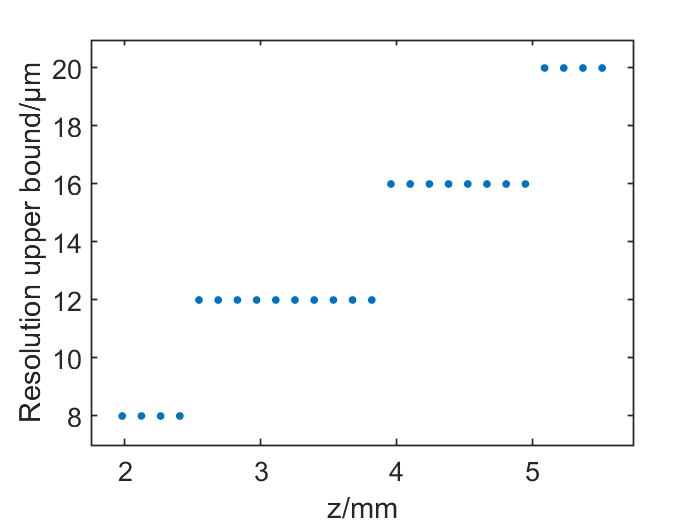

res_ratio=[D_15./sigma_15_R;D_10./sigma_10_R;D_8./sigma_8_R;D_6./sigma_6_R;D_4./sigma_4_R];

res_ind=NaN*zeros(1,N_z);
res_min=NaN*zeros(1,N_z);
res_low=NaN*zeros(1,N_z);
for n=1:N_z
    res_ratio_z=res_ratio(:,n);
    
    res_ind(n)=find(res_ratio_z>4,1,'last');
    
    switch res_ind(n)
        case 1
            res_min(n)=15*2;
            res_low(n)=10*2;
        case 2
            res_min(n)=10*2;
            res_low(n)=8*2;
        case 3
            res_min(n)=8*2;
            res_low(n)=6*2;
        case 4
            res_min(n)=6*2;
            res_low(n)=4*2;
        case 5
            res_min(n)=4*2;
            res_low(n)=2*2;
    end
end

%Plot the result
figure
plot(z2/1e3,res_min,'.','MarkerSize',16)
xlabel(['z/mm'])
ylabel(['Resolution upper bound/',char(181),'m'])
set(gca,'LineWidth',1,'FontSize',16)
ylim([7 21])
xlim([1.75 5.75])


% x2 = [z2, fliplr(z2)]/1e3;
% inBetween = [res_min, fliplr(res_low)];
% h=fill(x2, inBetween, [0, 0.4470, 0.7410],'LineStyle','none');
% set(h,'facealpha',.5)

%  exportgraphics(gcf,'..\Figures\Res_plot.pdf')
%  savefig(['..\Figures\Res_plot.fig'])

[xData, yData] = prepareCurveData( FWHM, res_min );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

m_res=fitresult.p1;

res_lin_err=confint(fitresult,0.6827);

m_res_err=diff(res_lin_err(:,1))/2;

Plot the CTF

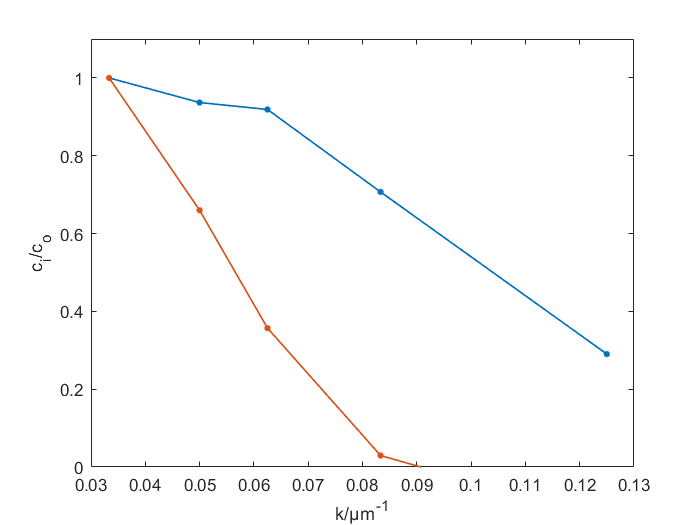

D_all=[D_15;D_10;D_8;D_6;D_4];
P_g=[15,10,8,6,4]*2;
k=1./P_g;
figure;plot(k,D_all(:,1)./D_all(1,1),'.-','LineWidth',1,'MarkerSize',12)
hold on
plot(k,D_all(:,15)./D_all(1,15),'.-','LineWidth',1,'MarkerSize',12)

xlabel(['k/',char(181),'m^{-1}'])
ylabel('c_i/c_o')
ylim([0 1.1])

Normalisation of this plot is very difficult and certainly wrong at the moment. The orange plot should be much lower, but I don't think I can know by how much easily.

## Plot examples of the line scans

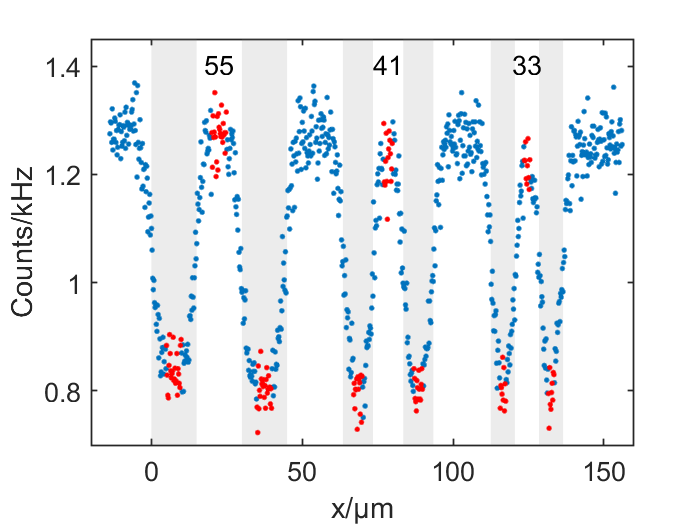

%Create posiitons of the gratings
x_patch15_1=[0,0,15,15];
x_patch15_2=x_patch15_1+30;

x_patch10_1=[64,64,74,74]-0.5;
x_patch10_2=x_patch10_1+20;

x_patch8_1=[112.5,112.5,120.5,120.5];
x_patch8_2=x_patch8_1+16;


y_patch_1=[700,1450,1450,700]/1000;

%Parameters for the grey box
alpha_value=0.15;
face_colour=[0.5,0.5,0.5];

%Create the plot
figure
n=1;
hold on
%Plot the grey boxes
patch(x_patch15_1,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch15_2,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch10_1,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch10_2,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch8_1,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch8_2,y_patch_1,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')

%Plot the data
plot(x-mu_z(n),data.image(:,n)/1000,'.','MarkerSize',10)
xlabel(['x/',char(181),'m'])
ylabel('Counts/kHz')
set(gca,'FontSize',16,'LineWidth',1)
xlim([-20 160])
ylim([700 1450]/1000)
%set(gca,'YTick',[700:100:1400]/1000)
hold on
box on


% Plot in chosen points
plot(x_comb(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n))-mu_z(n),combined_data(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n))-mu_z(n),combined_data(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_15_inds_lim(1,n):max_15_inds_lim(2,n))-mu_z(n),combined_data(max_15_inds_lim(1,n):max_15_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)

plot(x_comb(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n))-mu_z(n),combined_data(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n))-mu_z(n),combined_data(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_10_inds_lim(1,n):max_10_inds_lim(2,n))-mu_z(n),combined_data(max_10_inds_lim(1,n):max_10_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)

plot(x_comb(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n))-mu_z(n),combined_data(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n))-mu_z(n),combined_data(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_8_inds_lim(1,n):max_8_inds_lim(2,n))-mu_z(n),combined_data(max_8_inds_lim(1,n):max_8_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)


% Add in the average levels
% plot([x_comb(min_15_1_inds_lim(1,n))-mu_z(n),x_comb(min_15_1_inds_lim(2,n))-mu_z(n)],[I_min_15_1(n),I_min_15_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_15_2_inds_lim(1,n))-mu_z(n),x_comb(min_15_2_inds_lim(2,n))-mu_z(n)],[I_min_15_2(n),I_min_15_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_15_inds_lim(1,n))-mu_z(n),x_comb(max_15_inds_lim(2,n))-mu_z(n)],[I_max_15(n),I_max_15(n)],'r--','Linewidth',2)
%
% plot([x_comb(min_10_1_inds_lim(1,n))-mu_z(n),x_comb(min_10_1_inds_lim(2,n))-mu_z(n)],[I_min_10_1(n),I_min_10_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_10_2_inds_lim(1,n))-mu_z(n),x_comb(min_10_2_inds_lim(2,n))-mu_z(n)],[I_min_10_2(n),I_min_10_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_10_inds_lim(1,n))-mu_z(n),x_comb(max_10_inds_lim(2,n))-mu_z(n)],[I_max_10(n),I_max_10(n)],'r--','Linewidth',2)
%
% plot([x_comb(min_8_1_inds_lim(1,n))-mu_z(n),x_comb(min_8_1_inds_lim(2,n))-mu_z(n)],[I_min_8_1(n),I_min_8_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_8_2_inds_lim(1,n))-mu_z(n),x_comb(min_8_2_inds_lim(2,n))-mu_z(n)],[I_min_8_2(n),I_min_8_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_8_inds_lim(1,n))-mu_z(n),x_comb(max_8_inds_lim(2,n))-mu_z(n)],[I_max_8(n),I_max_8(n)],'r--','Linewidth',2)


% plot([x_comb(min_6_1_inds_lim(1,n))-mu_z(n),x_comb(min_6_1_inds_lim(2,n))-mu_z(n)],[I_min_6_1(n),I_min_6_1(n)],'k','Linewidth',2)
% plot([x_comb(min_6_2_inds_lim(1,n))-mu_z(n),x_comb(min_6_2_inds_lim(2,n))-mu_z(n)],[I_min_6_2(n),I_min_6_2(n)],'k','Linewidth',2)
% plot([x_comb(max_6_inds_lim(1,n))-mu_z(n),x_comb(max_6_inds_lim(2,n))-mu_z(n)],[I_max_6(n),I_max_6(n)],'k','Linewidth',2)
%
% plot([x_comb(min_4_1_inds_lim(1,n))-mu_z(n),x_comb(min_4_1_inds_lim(2,n))-mu_z(n)],[I_min_4_1(n),I_min_4_1(n)],'k','Linewidth',2)
% plot([x_comb(min_4_2_inds_lim(1,n))-mu_z(n),x_comb(min_4_2_inds_lim(2,n))-mu_z(n)],[I_min_4_2(n),I_min_4_2(n)],'k','Linewidth',2)
% plot([x_comb(max_4_inds_lim(1,n))-mu_z(n),x_comb(max_4_inds_lim(2,n))-mu_z(n)],[I_max_4(n),I_max_4(n)],'k','Linewidth',2)


%Plot the text labels
text(mean([x_comb(max_15_inds_lim(1,n)),x_comb(max_15_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+30)/1000,num2str(D_15(n)./sigma_15_R(n),2),'HorizontalAlignment','center','FontSize',16)
text(mean([x_comb(max_10_inds_lim(1,n)),x_comb(max_10_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+30)/1000,num2str(D_10(n)./sigma_10_R(n),2),'HorizontalAlignment','center','FontSize',16)
text(mean([x_comb(max_8_inds_lim(1,n)),x_comb(max_8_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+30)/1000,num2str(D_8(n)./sigma_8_R(n),2),'HorizontalAlignment','center','FontSize',16)
% text(mean([x_comb(max_6_inds_lim(1,n)),x_comb(max_6_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_6(n)./sigma_6_R(n),3),'HorizontalAlignment','center')
% text(mean([x_comb(max_4_inds_lim(1,n)),x_comb(max_4_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_4(n)./sigma_4_R(n),3),'HorizontalAlignment','center')



%  exportgraphics(gcf,'..\Figures\Line_scan_small.pdf')
%  savefig(['..\Figures\Line_scan_small.fig'])

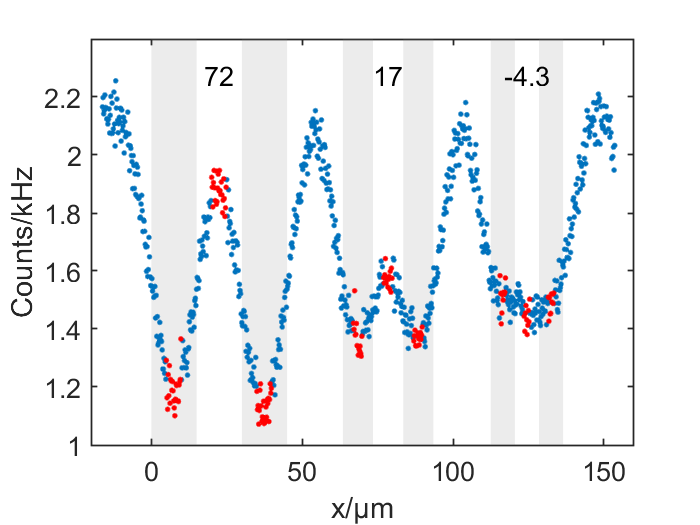


% Repeat for a diferent z position
figure
n=26;
hold on
box on
y_patch_2=[1000,2400,2400,1000]/1000;
patch(x_patch15_1,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch15_2,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch10_1,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch10_2,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch8_1,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')
patch(x_patch8_2,y_patch_2,face_colour,'FaceAlpha',alpha_value,'EdgeColor','none')


plot(x-mu_z(n),data.image(:,n)/1000,'.','MarkerSize',10)
xlabel(['x/',char(181),'m'])
ylabel('Counts/kHz')
set(gca,'FontSize',16,'LineWidth',1)
xlim([-20 160])
ylim([1000 2400]/1000)



% Plot in chosen points
plot(x_comb(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n))-mu_z(n),combined_data(min_15_1_inds_lim(1,n):min_15_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n))-mu_z(n),combined_data(min_15_2_inds_lim(1,n):min_15_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_15_inds_lim(1,n):max_15_inds_lim(2,n))-mu_z(n),combined_data(max_15_inds_lim(1,n):max_15_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)

plot(x_comb(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n))-mu_z(n),combined_data(min_10_1_inds_lim(1,n):min_10_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n))-mu_z(n),combined_data(min_10_2_inds_lim(1,n):min_10_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_10_inds_lim(1,n):max_10_inds_lim(2,n))-mu_z(n),combined_data(max_10_inds_lim(1,n):max_10_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)

plot(x_comb(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n))-mu_z(n),combined_data(min_8_1_inds_lim(1,n):min_8_1_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n))-mu_z(n),combined_data(min_8_2_inds_lim(1,n):min_8_2_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)
plot(x_comb(max_8_inds_lim(1,n):max_8_inds_lim(2,n))-mu_z(n),combined_data(max_8_inds_lim(1,n):max_8_inds_lim(2,n),n)/1000,'r.','MarkerSize',10)


% Add in the average levels
% plot([x_comb(min_15_1_inds_lim(1,n))-mu_z(n),x_comb(min_15_1_inds_lim(2,n))-mu_z(n)],[I_min_15_1(n),I_min_15_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_15_2_inds_lim(1,n))-mu_z(n),x_comb(min_15_2_inds_lim(2,n))-mu_z(n)],[I_min_15_2(n),I_min_15_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_15_inds_lim(1,n))-mu_z(n),x_comb(max_15_inds_lim(2,n))-mu_z(n)],[I_max_15(n),I_max_15(n)],'r--','Linewidth',2)
%
% plot([x_comb(min_10_1_inds_lim(1,n))-mu_z(n),x_comb(min_10_1_inds_lim(2,n))-mu_z(n)],[I_min_10_1(n),I_min_10_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_10_2_inds_lim(1,n))-mu_z(n),x_comb(min_10_2_inds_lim(2,n))-mu_z(n)],[I_min_10_2(n),I_min_10_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_10_inds_lim(1,n))-mu_z(n),x_comb(max_10_inds_lim(2,n))-mu_z(n)],[I_max_10(n),I_max_10(n)],'r--','Linewidth',2)
%
% plot([x_comb(min_8_1_inds_lim(1,n))-mu_z(n),x_comb(min_8_1_inds_lim(2,n))-mu_z(n)],[I_min_8_1(n),I_min_8_1(n)],'r--','Linewidth',2)
% plot([x_comb(min_8_2_inds_lim(1,n))-mu_z(n),x_comb(min_8_2_inds_lim(2,n))-mu_z(n)],[I_min_8_2(n),I_min_8_2(n)],'r--','Linewidth',2)
% plot([x_comb(max_8_inds_lim(1,n))-mu_z(n),x_comb(max_8_inds_lim(2,n))-mu_z(n)],[I_max_8(n),I_max_8(n)],'r--','Linewidth',2)


% plot([x_comb(min_6_1_inds_lim(1,n))-mu_z(n),x_comb(min_6_1_inds_lim(2,n))-mu_z(n)],[I_min_6_1(n),I_min_6_1(n)],'k','Linewidth',2)
% plot([x_comb(min_6_2_inds_lim(1,n))-mu_z(n),x_comb(min_6_2_inds_lim(2,n))-mu_z(n)],[I_min_6_2(n),I_min_6_2(n)],'k','Linewidth',2)
% plot([x_comb(max_6_inds_lim(1,n))-mu_z(n),x_comb(max_6_inds_lim(2,n))-mu_z(n)],[I_max_6(n),I_max_6(n)],'k','Linewidth',2)
%
% plot([x_comb(min_4_1_inds_lim(1,n))-mu_z(n),x_comb(min_4_1_inds_lim(2,n))-mu_z(n)],[I_min_4_1(n),I_min_4_1(n)],'k','Linewidth',2)
% plot([x_comb(min_4_2_inds_lim(1,n))-mu_z(n),x_comb(min_4_2_inds_lim(2,n))-mu_z(n)],[I_min_4_2(n),I_min_4_2(n)],'k','Linewidth',2)
% plot([x_comb(max_4_inds_lim(1,n))-mu_z(n),x_comb(max_4_inds_lim(2,n))-mu_z(n)],[I_max_4(n),I_max_4(n)],'k','Linewidth',2)


%Plot the text labels
text(mean([x_comb(max_15_inds_lim(1,n)),x_comb(max_15_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+20)/1000,num2str(D_15(n)./sigma_15_R(n),2),'HorizontalAlignment','center','FontSize',16)
text(mean([x_comb(max_10_inds_lim(1,n)),x_comb(max_10_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+20)/1000,num2str(D_10(n)./sigma_10_R(n),2),'HorizontalAlignment','center','FontSize',16)
text(mean([x_comb(max_8_inds_lim(1,n)),x_comb(max_8_inds_lim(2,n))])-mu_z(n),(max(combined_data(:,n))+20)/1000,num2str(D_8(n)./sigma_8_R(n),2),'HorizontalAlignment','center','FontSize',16)
% text(mean([x_comb(max_6_inds_lim(1,n)),x_comb(max_6_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_6(n)./sigma_6_R(n),3),'HorizontalAlignment','center')
% text(mean([x_comb(max_4_inds_lim(1,n)),x_comb(max_4_inds_lim(1,n))])-mu_z(n),min(combined_data(:,n))-10,num2str(D_4(n)./sigma_4_R(n),3),'HorizontalAlignment','center')



%  exportgraphics(gcf,'..\Figures\Line_scan_big.pdf')
%  savefig(['..\Figures\Line_scan_big.fig'])